**INSTITUTO POLITÉCNICO NACIONAL**

**UNIDAD PROFESIONAL INTERDISCIPLINARIA DE INGENIERÍA EN TECNOLOGÍAS AVANZADAS**

**Práctica 4:** Señales en tiempo discreto

**Materia:** Análisis de Señales y Sistemas

**Profesor:** Rafael Martínez Martínez

**Integrantes:**

Huerta Sánchez Jesus Alejandro.

Navarro Herrera Leon Ricardo.

Santos López Luis Enrique.

**GRUPO:** 2MV1

**Fecha de entrega:** 03/04/2020

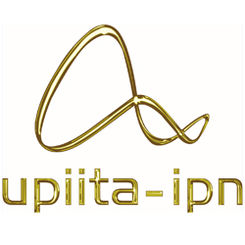                                                  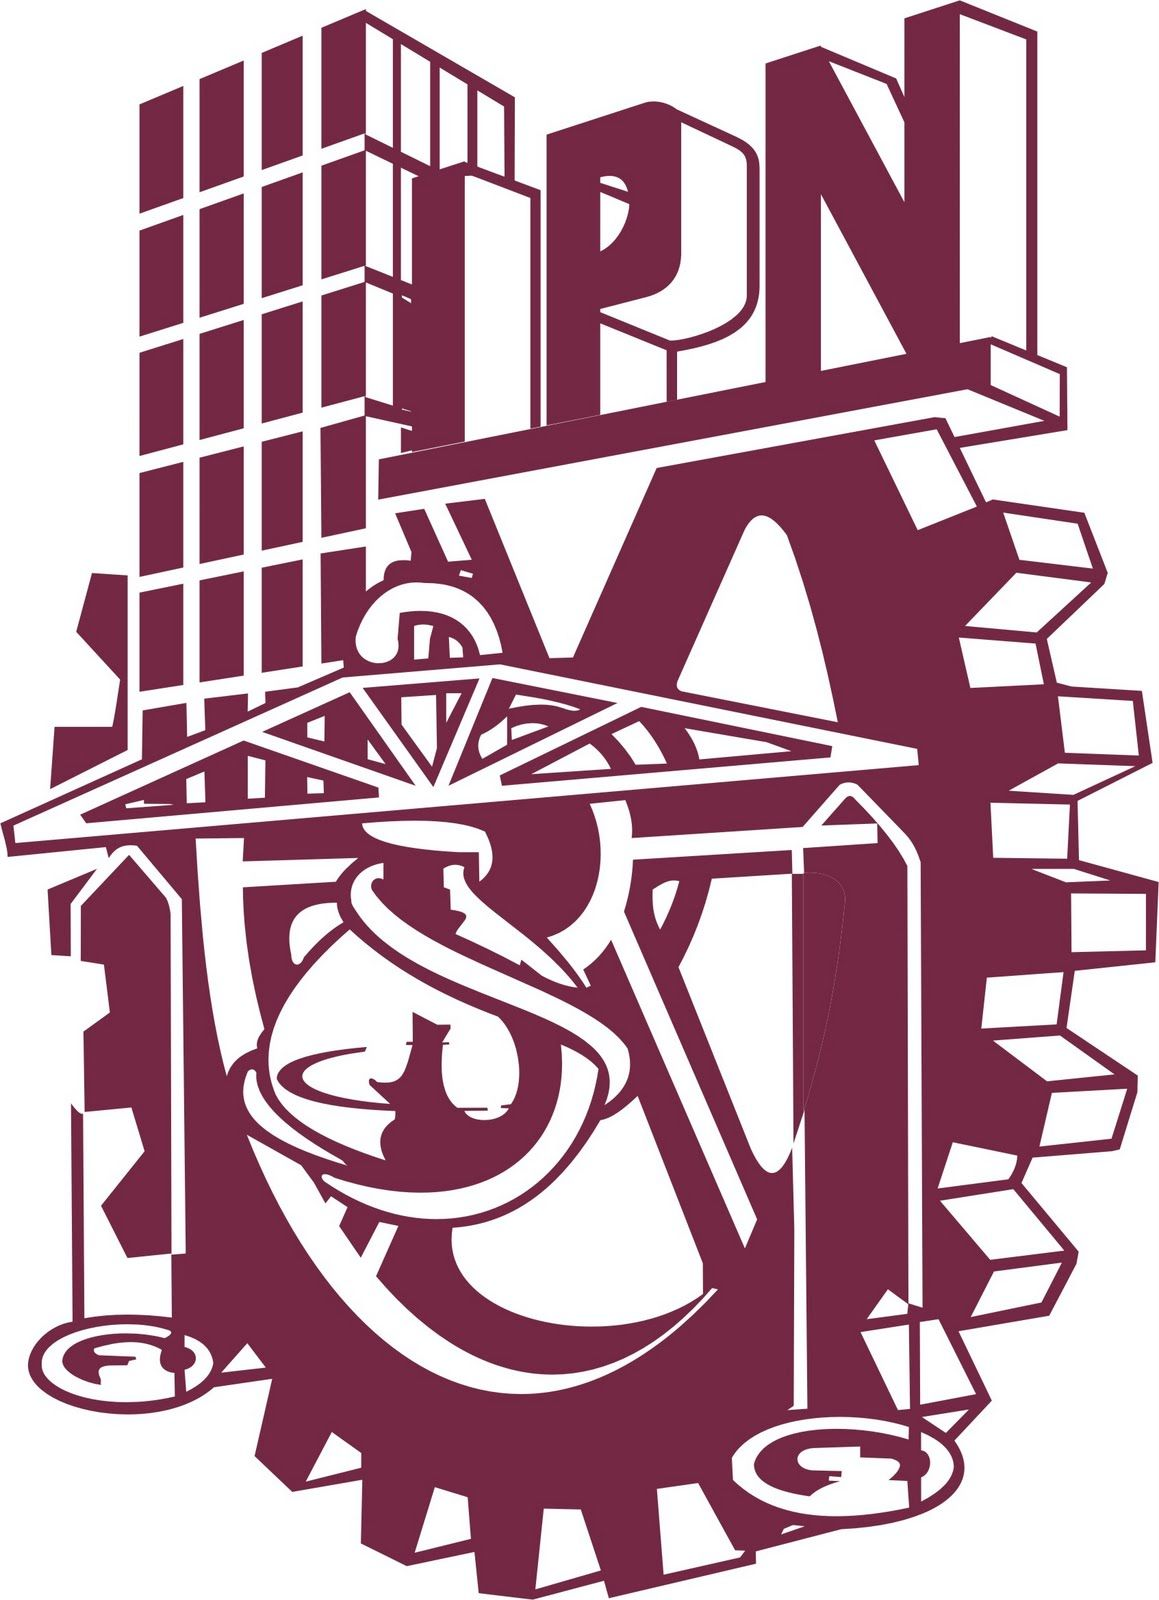

## Objetivos:

- Conocer métodos básicos de integración numérica

- Manipulación de instrucciones en MATLAB

- Simular convoluciones y correlaciones de señales continuas

- Simular convoluciones y correlaciones de señales discretas

## Introducción:

Existen diferentes métodos para ralizar la simulación numérica de una comvolución. La convolución se define como:


$$x_1 \left(t\right)*x_2 \left(t\right)=\int_{-\infty }^{\infty } x_1 \left(\tau \right)x_2 \left(t-\tau \right)d\tau$$


En la presente práctica se abordan convoluciones y 

Por lo que es necesario resolver la integral y se vuelve necesario entender que significa integrar numéricamente para poder inplementar un algoritmo que resuelva el problema, para esta implementación se debe tener en cuanta que es imposible hacer sululaciones que involucren cantidades infinitas, por lo que, si una señal tiene duración $T_1$ y la otra tuene duración $T_2$ la convolución tendra una duración $T_{1\;} +T_2$.

Integrar numericamente es buscar polinomios que "sustituyan" de cierto modo a las funciones y hacer la integral con esos polinomios, esta idea surge de ver el problema como un área bajo una curva que se desea encontrar, sin necesidad de implementar la idea del teorema fundamental del cálculo, las motivaciones para realizar este tipo de integración en lugar de la clásica que hasta ahora implementamos con la antiderivada son dos fundamentalmente.

- Existen funciones demasiado complejas que no se pueden describir fácilmente o cuya antiderivada no existe, en estos casos la integración clásica con el teorema fundamental del cálculo es demasiado complicada o no se puede hacer.

- Los programas computacionales utilizan este tipo de integración ya que es más práctico realizar este tipo de aproximaciones porque no pueden trabajar con un rango de valores infinito, solo muy grande y necesitan para resolver algunos problemas que se sustituyan expresiones por algunas menos complejas matematicamente hablando.

## Desarrollo

A continuación se llevan a cabo los puntos solicitados en la práctica.

### Problema 1

Para el PR04 reporte la grafica de la simulación númerica de la  convolución y compare con el resultado análitico que obtuvo para el  problema 1, esto es, su práctica tendrá que incluir una llamada a la  funciónn *convconm* y posteriormente se tendrá que mostrar  (mediante el Publish) la gráfica tanto de las señales involucradas como  el resultado de la convolución, y en esta última gráficara su resultado  analitico, se tendrá que incluir el resultado analitico.

El PR04  se tienen las siguientes señales $h(t)= \left\{ \begin{array}{lcc}
             t &   si  & -1\leq t\leq 1 \\
             0 & si & Otro caso \\
             \end{array}
   \right.$


$$x(t)= \left\{ \begin{array}{lcc}
             e^{-t} &   si  & 0\leq t\leq 1 \\
             0 & si & Otro caso \\
             \end{array}
   \right.$$


Y el resultado analitico es 


$$x(t)\ast h(t)= \left\{ \begin{array}{lcc}
             2e^{-t-1}+t-1 & si & t\leq -1 \\
             t-e^{-1}(t-2)-1 & si & 0\leq t\leq 1 \\
             -e^(-1)(t-2) & si & 1\leq t\leq 2 \\
             0 & si & Otro-caso \\
             \end{array}
   \right.$$


Ahora se puede implementar las graficas en matlab 

figure
subplot(1,3,1)
syms t
x=piecewise(t<0,0,0<t<1,exp(-t),t>1,0);
fplot(x,[-3 3],'r')
grid on
title('x(t)')
axis([-1 3.6 -2 2]);
subplot(1,3,2)
h=piecewise(t<-1,0,-1<t<1,t,t>1,0);
fplot(h,[-5,3],'r')
grid on
title('h(t)')
axis([-2 3.6 -2 2]);
t1=-1:0.01:0;
t2=0:0.01:1;
t3=1:0.01:2;
subplot(1,3,3)
plot(t1,2*exp(-t1-1)+t1-1);
hold on
plot(t2,t2-exp(-1)*(t2-2)-1);
plot(t3,-exp(-1)*(t3-2));
grid on
title('x(t)*h(t)');
axis([-2 3.6 -2 2]);

El siguiente código es una modificación del código de Lathi (Código del  capítulo 2, M2.4 pág 161), ejemplo de convoluciones continuas

Si ejecutamos las siguientes instrucciones en el Command Window y el  directorio de trabajo es el mismo donde se encuentra la función *convconm* tendrémos el siguiente resultado

x = @(t) exp(-t).*(t>=0 & t<=1);
h = @(t) t.*(t>=-1 & t<=1 );
convconm(x,h)

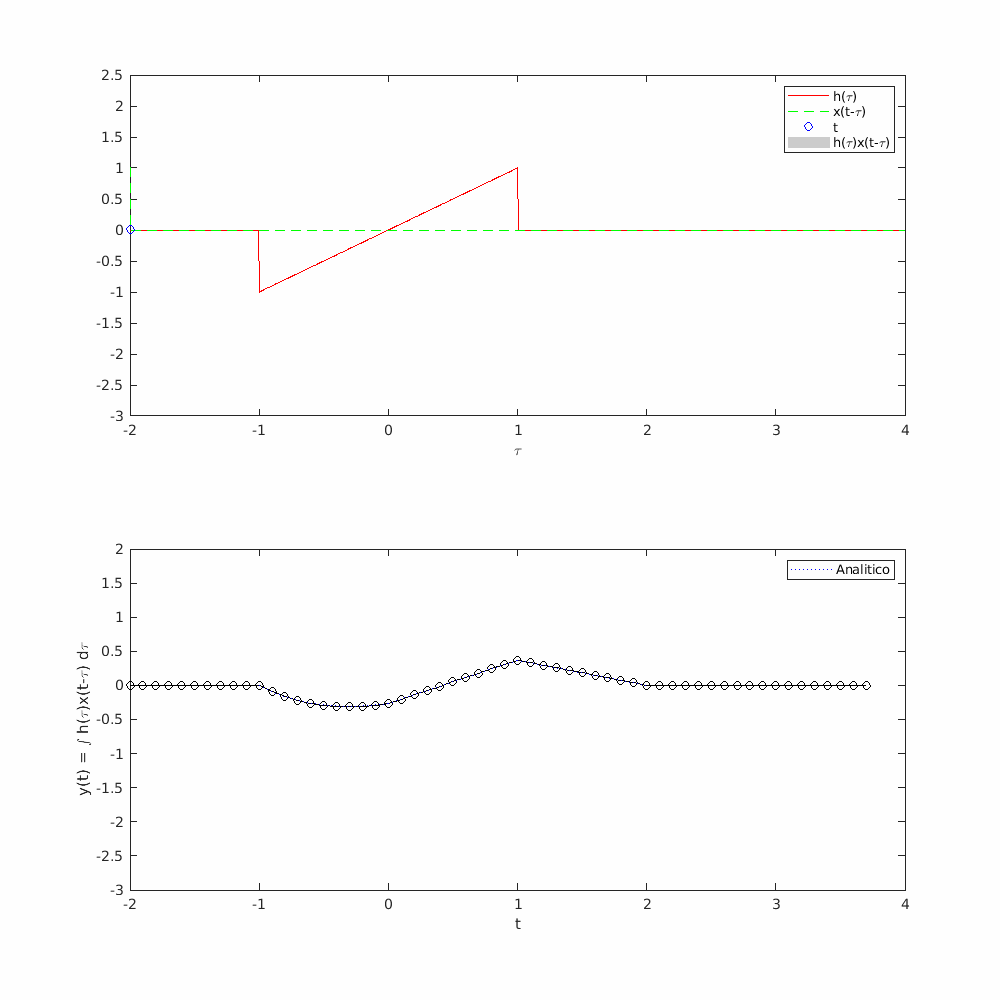

Por lo que el resultado coincide el obtenido por la integración numérica y el que ya teníamos analiticamente.

### Problema 2

### Problema 3

La convolución de señales en tiempo discreto da como resultado otra señal en tiempo discreto, la operación se define como:


$$x_3 \left\lbrack n\right\rbrack =\sum_{m=-\infty }^{\infty } x_1 \left\lbrack m\right\rbrack x_2 \left\lbrack n-m\right\rbrack$$


No es posible obtener el resultado de esta operacion para señales de longitud infinita mediante calculos computacionales, por lo que es necesario acotar nuestra descripción a señales causales de longitud finita, considerando que:

- Si la señal $x_{1\;}$tiene longitud $T_1$ y la señal $x_2$ tiene longitud $T_2$ la señal $x_3$ tendra longitud $T_1 +T_2 -1$

- La intrucción **conv **de MATLAB ayuda a calcular las convoluciones.

A continuación se muestra el código de la función usada para realizar una simulación de la convolución de las señales (c) y (d) del problema 3.1.1 de Lathi.

Si ejecutamos las siguientes instrucciones en el Command  Window y el directorio de trabajo es el mismo donde se encuentra la función *convdisc *obtendrémos el siguente resultado.

n=0:9;
a=[0 0 4 2 0 2 4 0 0 0 ];
b=[0 -9 -6 -3 0 3 6 9 0 0];
convdisc([n;a],[n;b])

im

Y observamos como se construye la gráfica según avanza la señal móvil.

### Problema 4

La correlación de las señales $x_1$ y $x_2$ puede definirse a partir de la convolución, esto es:


$$r_{x_1 x_2 } \left\lbrack n\right\rbrack =x_1 \left\lbrack n\right\rbrack *x_2 \left\lbrack n\right\rbrack$$


Para usar el código de convolución para obtener la correlación de las  señales (c) y (d) del problema 3.1.1 de Lathi, debemos escribir en el Command Window.

n=0:9;
a=[0 0 4 2 0 2 4 0 0 0 ];
b=[0 -9 -6 -3 0 3 6 9 0 0];
m=length(b);
b=b(m:-1:1)
convdisc([n;a],[n;b])

Con lo que obtendremos la siguiente salida.

im

### Problema 5

Convolución de las señales (c) y (d) del problema 3.1.1 Lathi mediante el uso del comando ***conv*** de MATLAB.

 A continuación se muestra el código de la función usada para realizar una simulación. 

A continuación introducimos la información de las señales en el Command Window.

clear all;
clc;
na = -4:1:5 
a=[0 0 4 2 0 2 4 0 0 0 ];
nb = -4:1:5 
b=[0 -9 -6 -3 0 3 6 9 0 0];
[nc,c] = convdisc2(a,na,b,nb);
 

Con lo que tendremos la siguiente salida.

im

La cual coincide con la obtenida anteriormente.